## Parameter Pre-Setting

clear 
clc

V0 = 0.895;             % input swing
C1 = 38.72E-12;         % load cap
Fs = 100E6;             % sample rate
VDD = 1.8;              % supply
Vth = 0.457;            % threshold voltage
Fi = (499/1024)*Fs;     % input frequency (Hz)

wi = (2*pi)*Fi;         


## Ron vs HD

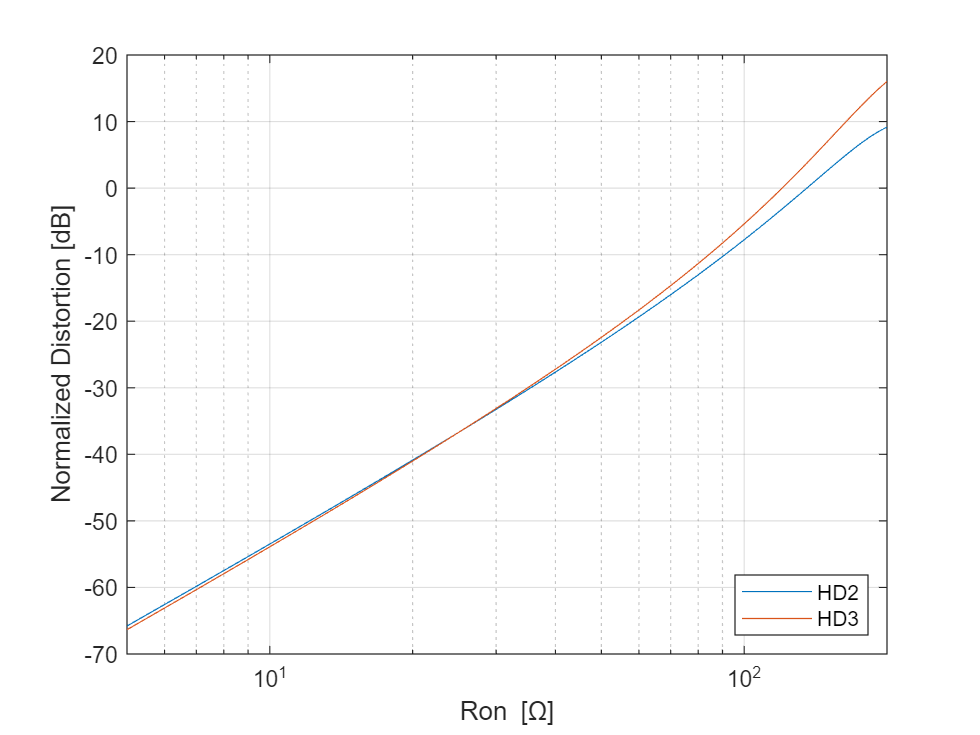

ron = linspace(5,200,100);
hd_ron = getHD_new(ron, V0, C1, Fi, -0.85);
% alpha = -0.85 for L = 200n;

figure
semilogx(ron, hd_ron);
grid on; box on;
xlabel("Ron [\Omega]");
ylabel("Normalized Distortion [dB]");
legend({'HD2', 'HD3'}, "Location", "southeast");

## Fin vs HD

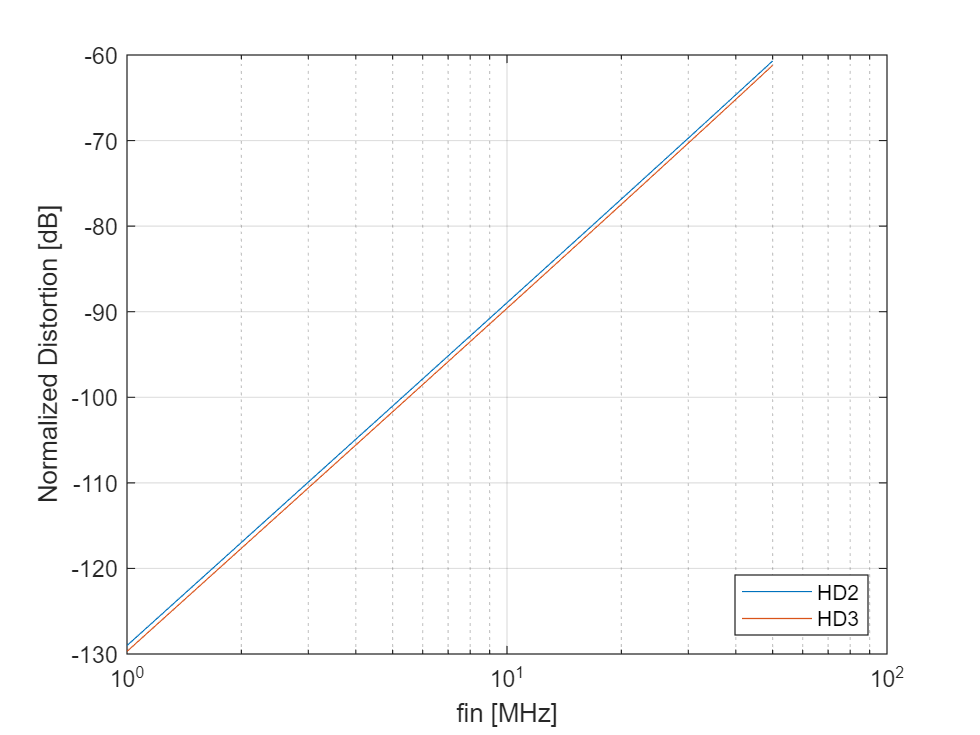

fin = linspace(0.01,0.5,100).*Fs;
hd_fin = getHD_new(6.5, V0, C1, fin, -0.85);
% ron = 6.5 ohm for w/L = 32*3u/200n;

figure
semilogx(fin./(1E6), squeeze(hd_fin(1,:,:)));
grid on; box on;
xlabel("fin [MHz]");
ylabel("Normalized Distortion [dB]");
legend({'HD2', 'HD3'}, "Location", "southeast");

## Fin & Ron vs HD

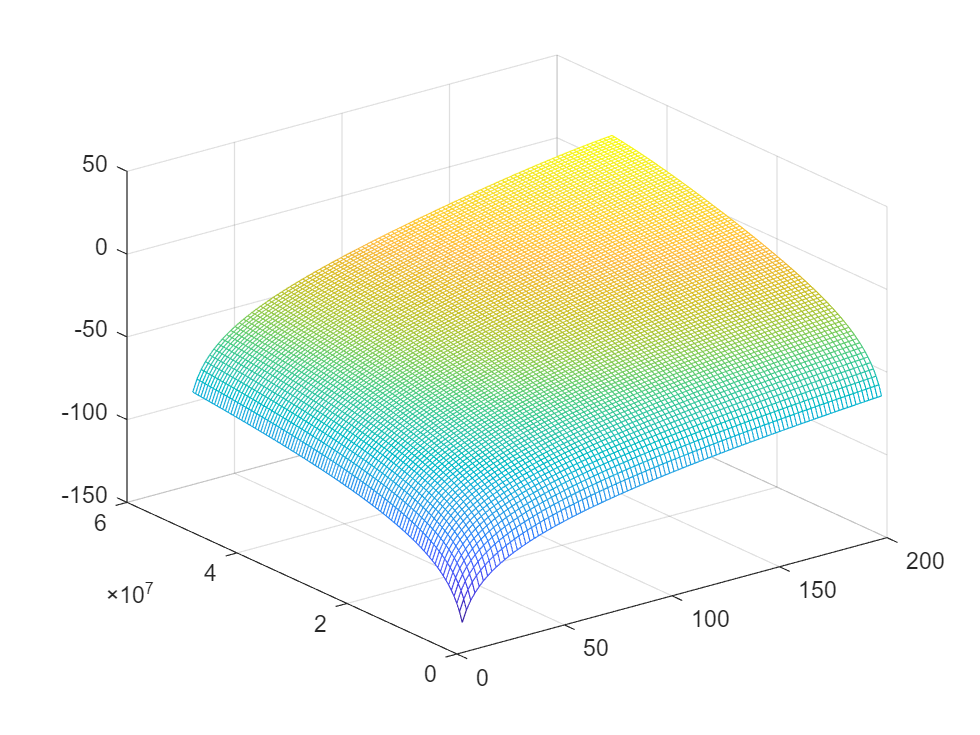

hd_tot = getHD_new(ron, V0, C1, fin, -0.85);
hd_tot3 = squeeze(hd_tot(:,2,:));
figure
mesh(ron, fin, hd_tot3);

% 三维图的结果并不明确，看不出有什么特别之处；
